% Define x values and their sine values
x_nodes = [0, pi/2, pi, 3*pi/2, 2*pi];
y_nodes = sin(x_nodes);

% Define fine x values for plotting
x_plot = linspace(0, 2*pi, 100);

% Natural spline: second derivative = 0 at endpoints
y_natural_spline = spline(x_nodes, [0 y_nodes 0], x_plot);

% Clamped spline: first derivatives (cos) at endpoints
deriv_at_ends = [cos(0), cos(2*pi)];
y_clamped_spline = spline(x_nodes, [deriv_at_ends(1) y_nodes deriv_at_ends(2)], x_plot);

% Evaluate both splines at x = pi/4
x_test = pi/4;
y_true = sin(x_test);
y_natural_eval = spline(x_nodes, [0 y_nodes 0], x_test);
y_clamped_eval = spline(x_nodes, [deriv_at_ends(1) y_nodes deriv_at_ends(2)], x_test);

% Display results
disp(['True value at π/4: ', num2str(y_true)]);

True value at π/4: 0.70711


disp(['Natural Spline at π/4: ', num2str(y_natural_eval)]); %0.85

Natural Spline at π/4: 0.44643


disp(['Clamped Spline at π/4: ', num2str(y_clamped_eval)]);

Clamped Spline at π/4: 0.69888


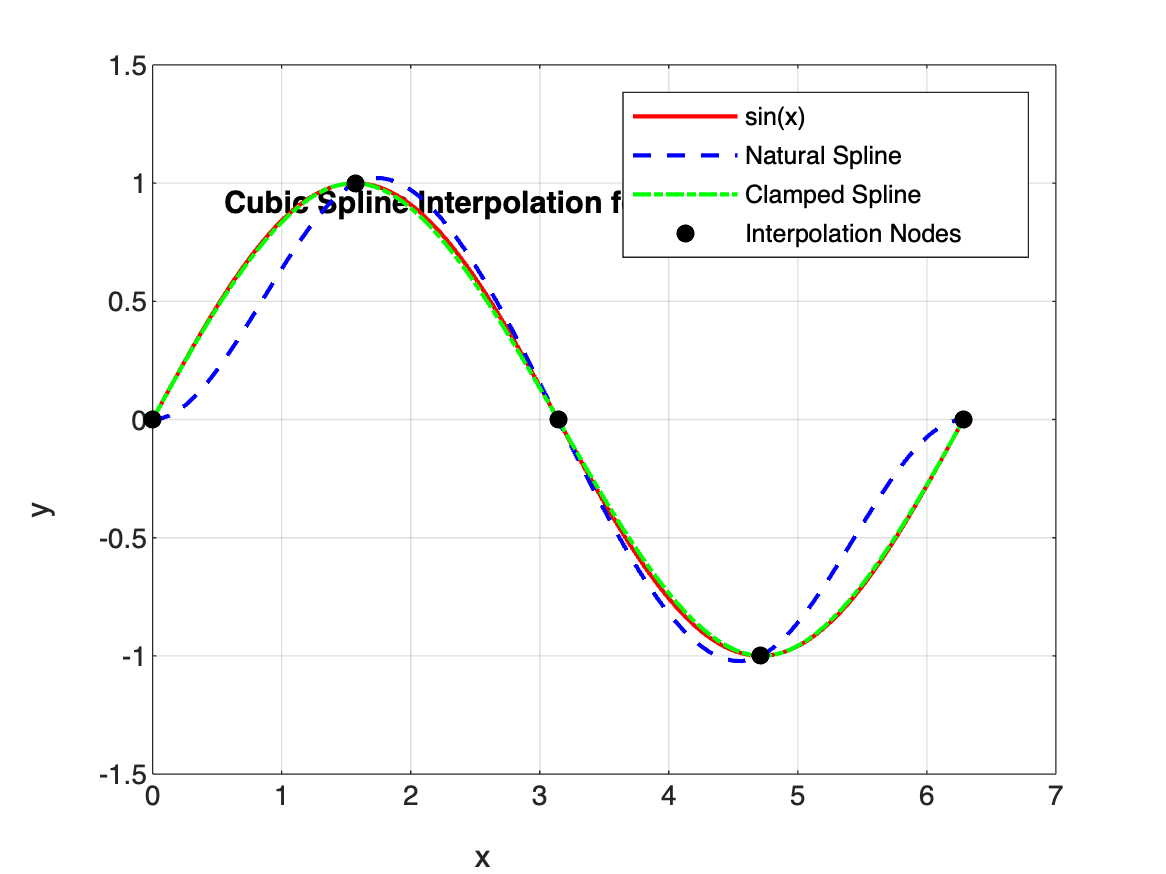

% Plot all
figure;
plot(x_plot, sin(x_plot), 'r', 'LineWidth', 1.5); hold on;
plot(x_plot, y_natural_spline, 'b--', 'LineWidth', 1.5);
plot(x_plot, y_clamped_spline, 'g-.', 'LineWidth', 1.5);
plot(x_nodes, y_nodes, 'ko', 'MarkerFaceColor', 'k');
legend('sin(x)', 'Natural Spline', 'Clamped Spline', 'Interpolation Nodes');
title('Cubic Spline Interpolation for sin(x)');
xlabel('x'); ylabel('y');
grid on;

## Exercise 2: Natural spline through 5 clicked points

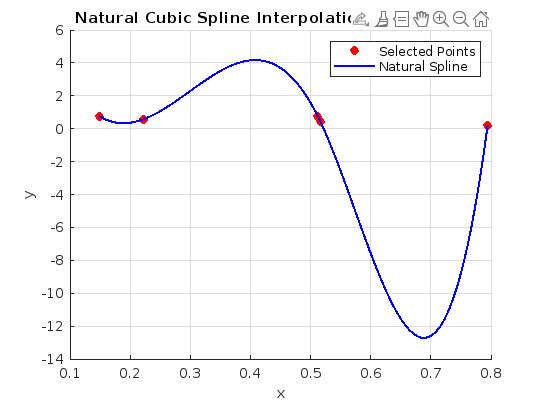

figure;
hold on;
title('Click 5 points, then press Enter');

% User clicks 5 points
[x_clicked, y_clicked] = ginput(5);

% Plot selected points
plot(x_clicked, y_clicked, 'ro', 'MarkerFaceColor', 'r');

% Fit natural spline and plot it
x_spline = linspace(min(x_clicked), max(x_clicked), 100);
y_spline = spline(x_clicked, y_clicked, x_spline);
plot(x_spline, y_spline, 'b', 'LineWidth', 1.5);

legend('Selected Points', 'Natural Spline');
title('Natural Cubic Spline Interpolation (User Points)');
xlabel('x'); ylabel('y');
grid on;

## Exercise 3: Estimate car position and speed using clamped spline


% Given time, distance, and speed data
time_data = [0, 3, 5, 8, 13];
position_data = [0, 225, 383, 623, 993];
speed_data = [75, 77, 80, 74, 72];

% Time to evaluate interpolation
time_query = 10;

% Clamped spline for distance 
estimated_position = spline(time_data, [0 position_data 0], time_query);

% Clamped spline for speed 
estimated_speed = spline(time_data, [0 speed_data 0], time_query);

% Display results
disp(['Estimated Position at t = 10s: ', num2str(estimated_position), ' feet']);

Estimated Position at t = 10s: 821.0299 feet


disp(['Estimated Speed at t = 10s: ', num2str(estimated_speed), ' feet/s']);

Estimated Speed at t = 10s: 71.7721 feet/s
